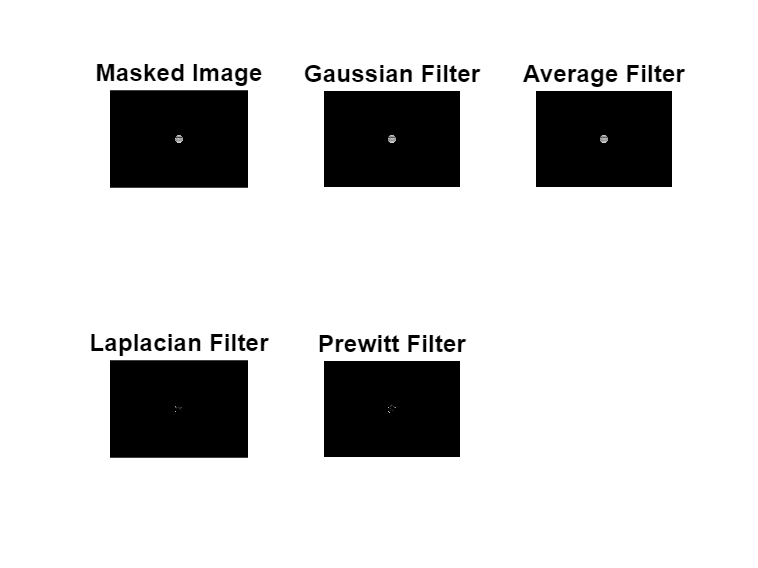

% Read and process the image
inputImage = imread('https://st4.depositphotos.com/6903990/27898/i/1600/depositphotos_278981062-stock-photo-beautiful-young-woman-clean-fresh.jpg'); % Load the image

grayscaleImage = rgb2gray(inputImage); % Convert to grayscale

% Create a circular binary mask
[imageHeight, imageWidth] = size(grayscaleImage);
imageCenter = [imageHeight / 2, imageWidth / 2]; % Define the center of the image
maskRadius = 50; % Define the radius of the circular mask

% Create a grid for the mask and apply circular masking
[xGrid, yGrid] = meshgrid(1:imageWidth, 1:imageHeight);
circularMask = (xGrid - imageCenter(2)).^2 + (yGrid - imageCenter(1)).^2 <= maskRadius^2;

% Apply the circular mask to the grayscale image
maskedImage = uint8(double(grayscaleImage) .* circularMask);

% Low-pass filters (blurring)
gaussianFilter = fspecial('gaussian', [5, 5], 2); % Gaussian filter (5x5, sigma=2)
averageFilter = fspecial('average', [5, 5]); % Average filter (5x5)

% Apply low-pass filters
blurredWithGaussian = imfilter(maskedImage, gaussianFilter);
blurredWithAverage = imfilter(maskedImage, averageFilter);

% High-pass filters (edge detection)
laplacianFilter = fspecial('laplacian', 0); % Laplacian filter (detects edges)
prewittFilter = fspecial('prewitt'); % Prewitt filter (horizontal edge detection)

% Apply high-pass filters
edgesWithLaplacian = imfilter(maskedImage, laplacianFilter);
edgesWithPrewitt = imfilter(maskedImage, prewittFilter);

% Display the results
figure;
subplot(2, 3, 1); imshow(maskedImage); title('Masked Image'); % Display masked image
subplot(2, 3, 2); imshow(blurredWithGaussian); title('Gaussian Low-Pass Filter'); % Display Gaussian filtered image
subplot(2, 3, 3); imshow(blurredWithAverage); title('Average Low-Pass Filter'); % Display average filtered image
subplot(2, 3, 4); imshow(edgesWithLaplacian); title('Laplacian High-Pass Filter'); % Display Laplacian edges
subplot(2, 3, 5); imshow(edgesWithPrewitt); title('Prewitt High-Pass Filter'); % Display Prewitt edges
